T = readtable('data.dat');%read data file
K = table2array(T);%put into array
numberOfDimensions = 3;%set num of dimensions to 3
[COEFF, SCORE, LATENT, TSQUARED, EXPLAINED] = pca(K); % Perform PCA analysis

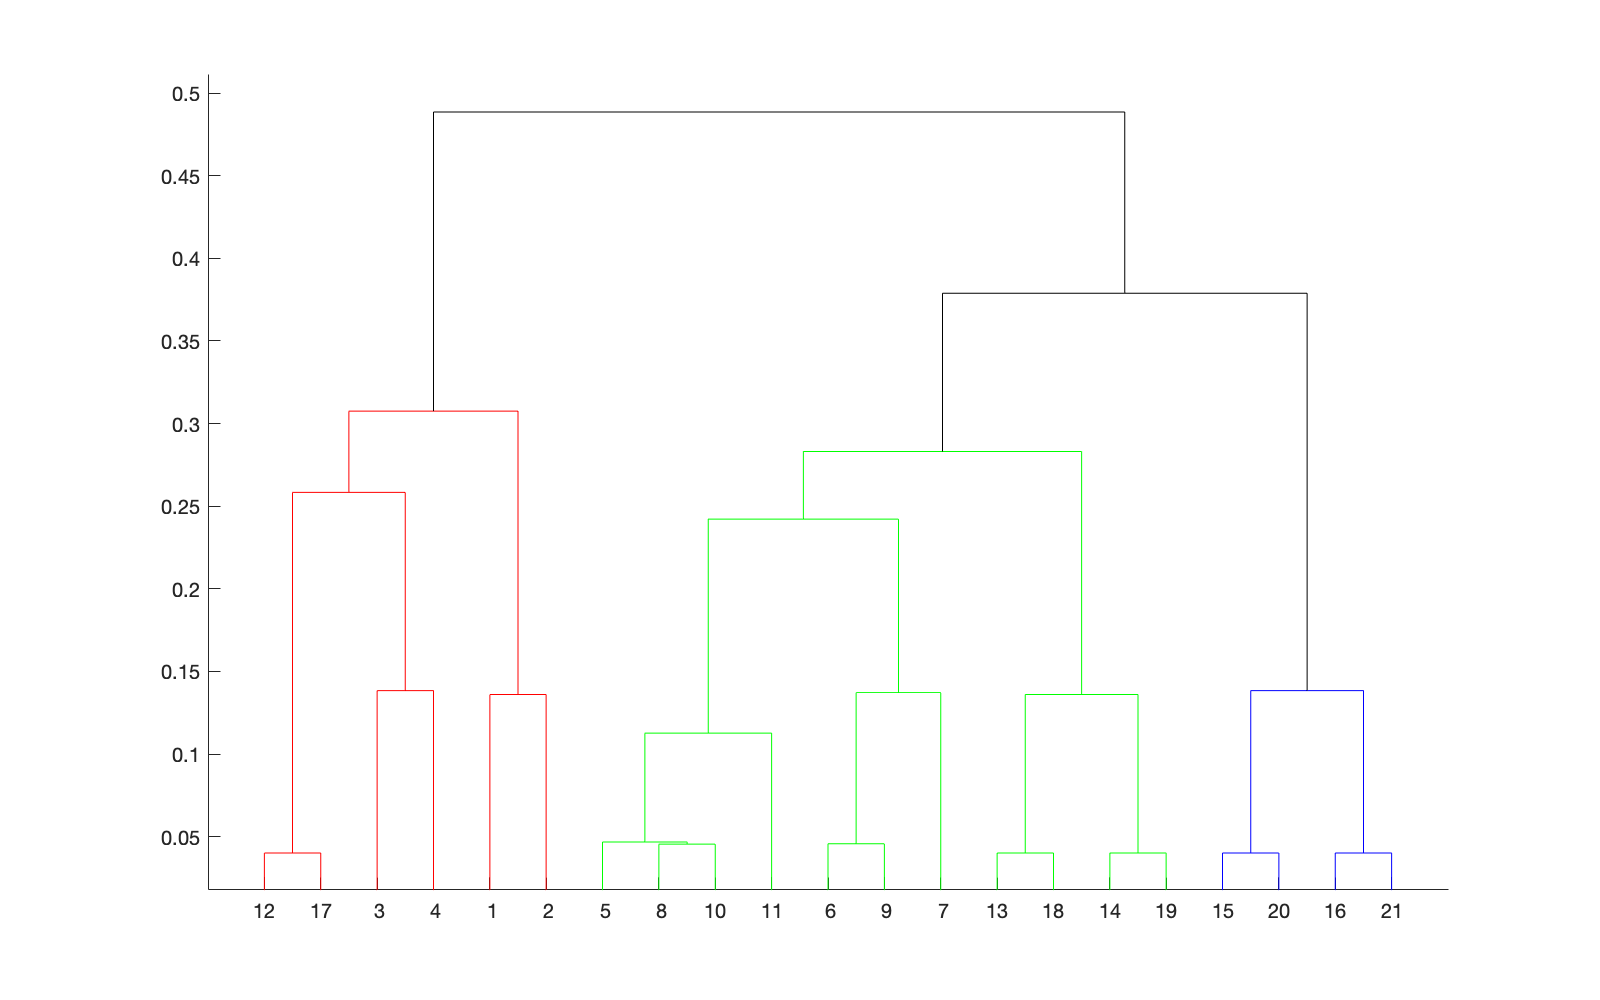

reducedDimension = COEFF(:,1:numberOfDimensions);% Use reduced dimentions
S = linkage(reducedDimension,'average','chebychev');%get average distances
W = cluster(S,'maxclust',3);%Put into 3 clusters
cutoff = median([S(end-2,3) S(end-1,3)]);%Make a cutoff value
dendrogram(S,'ColorThreshold',cutoff)%display as dendrogram